# Hybrid Electric Vehicle Model in Simscape

This is a MATLAB project containing a power-split hybrid electric vehicle (HEV) model. Click the button below to open the model.

 
open_system("PowerSplitHEV_system_model")

## Project Overview

Power-split HEV is a series-parallel hybrid system and has a planetary gear to split the power from a combustion engine to driving the axle and generating the electrical power. The picture below is a high-level schematic of the power-split drive unit where the motor-generator 1 (MG1) and the engine are connected to the planetary gear, and the MG2 and the planetary gear are linked via a reduction gear which is connected to the axle.

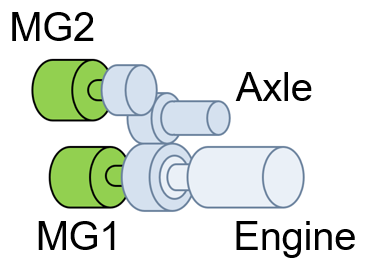

Power-Split Drive Unit

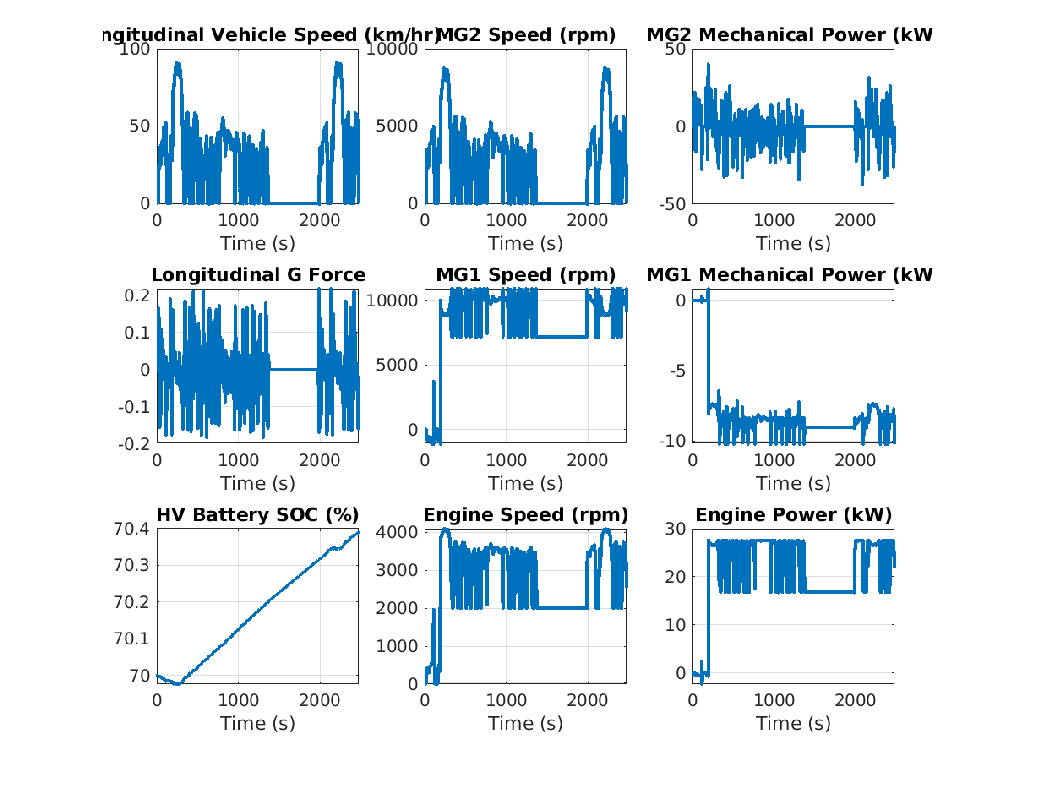

PowerSplitHEV_SpeedTracking_example("FTP75")

## Power-Split HEV Model

The HEV model consists of components such as longitudinal vehicle, power-split drive unit with an internal combustion engine and two electric motors, DC-DC converter, high-voltage battery, and hybrid powertrain controller. By default, the model is configured with abstract components in referenced subsystems. It can run faster than real-time in typical desktop computers. The model is also suitable for further customizations for more focused analysis of individual components at vehicle level.

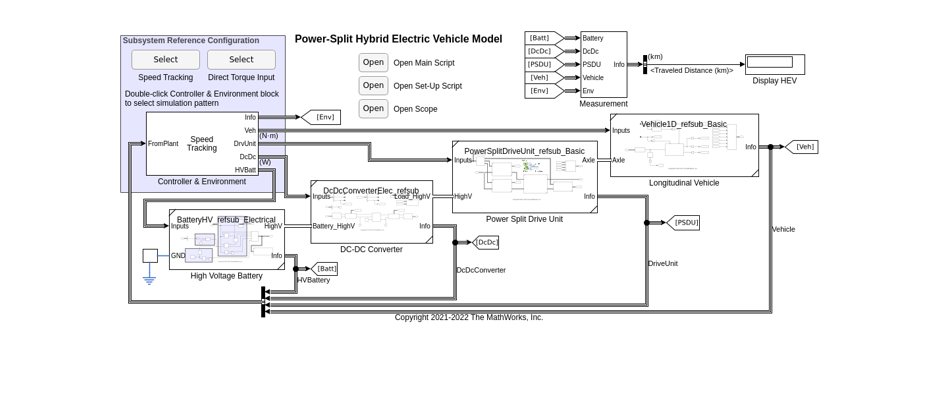

% Update model for a screenshot.
set_param("PowerSplitHEV_system_model", SimulationCommand = "update")

screenshotSimulink( ...
  SimulinkModelName = "PowerSplitHEV_system_model", ...
  SaveFolder = currentProject().RootFolder + "/Utility", ...
  OutputImageWidth_px = 700 );
img = imread(currentProject().RootFolder + "/Utility/image_PowerSplitHEV_system_model.png");
figure
imshow(img)

The HEV model can be used with two different controllers: **speed tracking** controller and **direct torque input** controller. These controllers are provided as referenced subsystems. You can use one of them for the Controller & Environment block in the HEV model.

**Speed tracking** controller takes reference vehicle speed as input and controls the drive unit so that the vehicle tracks the reference. Use this controller for dricve cycle simulation and vehicl system-level anaylsis such as energy efficiency study.

**Direct torque input** controller is a simple torque source which takes torque commands to an engine and two motors as input and simply send them to the drive unit. Use this to examine system behaviors for predefined torque command sequences.

For more details, see the **Power-Split HEV main script**, which you can open by clicking the button below.

 
edit("PowerSplitHEV_main_script.mlx")

## Workflows

### Parameter Sweep Workflow for Electrical Efficiency Analysis

Investigate the impact of the reduction gear ratio and the capacity and weight of high-voltage battery on the vehicle electrical efficiency. Click the button below to open the workflow script.

 
edit("PowerSplitHEV_SpeedTracking_sweep.mlx")

## Components

The HEV model is built in a modular manner using **Subsystem Reference** for high-voltage battery, DC-DC converter, power-split drive unit, longitudinal vehicle, and controller-and-environment blocks. These components are built individually and integrated in the HEV model as referenced subsystems, making it easy to work both at individual component level and at vehicle system level. For more information about Subsystem Reference, see the documentation:

- [Subsystem Reference - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/simulink/ug/referenced-subsystem-1.html)

Some of the components come with individual harness models to test in an isolated mannar. You can open these models from the Project Shortcuts tab in the Project Toolstrip.

## MATLAB Project & Git Source Control

The development of this project is managed by Git source control, and the repository is hosted at GitHub.

- [https://github.com/mathworks/Simscape-Hybrid-Electric-Vehicle-Model](https://github.com/mathworks/Simscape-Hybrid-Electric-Vehicle-Model)

If you download archive file from GitHub, it includes MATLAB Project files without Git repository data. You can start using Git in such a project. See the documentation for more information:

- [Use Source Control with Projects - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/matlab_prog/use-source-control-with-projects.html)

To obtain the project with Git repository data, you can fork the repository in GitHub if you have a GitHub account. You can also clone the remote repository in your local machine and develop for your own needs. See the documentation for more information:

- [Use Git in MATLAB - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/matlab_prog/use-git-in-matlab.html)

- [Clone Remote Git Repository into New Project - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/matlab_prog/clone-from-git-repository.html)

## Unit Test

The HEV model and some of the components come with unit tests. You can find the unit test implementation in the `test` folders. The `testcases` folders have Live Scripts, each of which runs a particular test simulation and makes the plots of simulation result for visual inspection.

### Unit Test Implementation

As an example, click the button below to open the unit test implementation for Power-Split Drive Unit component.

 
edit("PowerSplitDriveUnit_Component_UnitTest_MQC.m")

For more information:

- [Author Class-Based Unit Tests in MATLAB - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/matlab_prog/author-class-based-unit-tests-in-matlab.html)

### Component-Level Test Runner for Single Component

Unit test runner drives unit tests and generates a result summary and a code coverage report. To test a single component, run this script. As an example, click the button below to open the test runner script for Power-Split Drive Unit.

 
edit("PowerSplitDriveUnit_Component_runtests.m")

For more information:

- [Class for running tests in matlab.unittest framework - MATLAB (mathworks.com)](https://www.mathworks.com/help/matlab/ref/matlab.unittest.testrunner-class.html)

### Project-Level Test Runner for All Unit Tests

Test runner at the project level is configured to automatically find all unit test implementation files within the project, runs all of them, and produces a test result report. Click the button below to open the project-level test runner script.

 
edit("HEVProject_runtests.m")

For more information:

- [Generate Code Coverage Report in HTML Format - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/matlab_prog/generate-code-coverage-report-in-html-format.html)

## Continuous Integration

The repository of this project at GitHub is configured to use GitHub Actions Continuous Integration to automatically run the project-level test runner when the repository at GitHub is updated. MATLAB and toolboxes are publicly available for use in GitHub Actions if the repository in GitHub is public.

GitHub Actions CI for this project is configured in the `ci.yml` file. Click the button below to open the file.

 
edit(currentProject().RootFolder + "/.github/workflows/runtests.yml")

For more information:

- [GitHub Actions Documentation - GitHub Docs](https://docs.github.com/en/actions)

- [matlab-actions/overview: Automate your workflows with GitHub actions for MATLAB.](https://github.com/matlab-actions/overview)

*Copyright 2021-2023 The MathWorks, Inc.*